%% demo_Regions_loaded.mlx
clear; clc; close all;

%% ===================== Reproducibility note =====================
% This script reproduces the region-comparison figure from a saved release pack:
%
%   Explicit mpQP:
%       The public parametric-QP model is rebuilt and solved explicitly.
%
%   Cert:
%       The proposed certified executor is loaded as a prebuilt deployment object.
%       The offline certified-library construction is not rerun in this loaded demo.
%
% The released XTrain and YTrain are included for transparency and optional checks.

%% ===================== Initialization =====================
rng(0);

%% ===================== Load release package =====================
release_mat = 'demo_Regions_release_pack.mat';
load(release_mat, 'problem', 'qp_cfg', 'train_data', 'cert_info', 'plot_cfg', 'ctrl');

nxi = problem.nxi;
nu  = problem.nu;
nz  = problem.nz;
Vz  = problem.Vz;
Rz  = problem.Rz;
G   = problem.G;
S   = problem.S;
b   = problem.b;

H      = qp_cfg.H;
Amap   = qp_cfg.Amap;
xi_c   = qp_cfg.xi_c;
F      = qp_cfg.F;
f      = qp_cfg.f;

XTrain   = train_data.XTrain;
YTrain   = train_data.YTrain;
Ntrain   = train_data.Ntrain;
train_box = train_data.train_box;
view_box  = train_data.view_box;

OPCert = ctrl.OPCert;
if isa(OPCert, 'Cert')
    if isprop(OPCert, 'mex_ready'), OPCert.mex_ready = false; end
    if isprop(OPCert, 'mex_id'),    OPCert.mex_id    = [];    end
end

fprintf(['\n==================== REGIONS LOADED DEMO ====================\n' ...
         '[Load] %s\n' ...
         '[Interface] nxi=%d, nu=%d, m=%d, Xi bounded? %d, U-rec rays=%d\n' ...
         '[Data] XTrain=%d-by-%d, YTrain=%d-by-%d\n' ...
         '[Cert] nLaw=%d, nAct=%d, cover=%s\n'], ...
         release_mat, nxi, nu, size(G, 1), problem.xi_bounded, problem.nRayU, ...
         size(XTrain, 1), size(XTrain, 2), size(YTrain, 1), size(YTrain, 2), ...
         cert_info.nLaw, cert_info.nAct, cert_info.cover_status);


==================== REGIONS LOADED DEMO ====================
[Load] demo_Regions_release_pack.mat
[Interface] nxi=2, nu=2, m=59, Xi bounded? 0, U-rec rays=2
[Data] XTrain=2-by-20000, YTrain=2-by-20000
[Cert] nLaw=71, nAct=23, cover=certified



%% ===================== Rebuild public polyhedral interface =====================
Ph = Polyhedron('V', Vz, 'R', Rz).minHRep();
Pxi = Ph.projection(1:nxi).minHRep();

fprintf('[QP] min eig(H)=%.3e\n', min(eig(H)));

[QP] min eig(H)=7.353e-01



%% ===================== Rebuild public explicit mpQP baseline =====================
ops_qp = sdpsettings('solver', qp_cfg.solver, 'verbose', 0);
[xi_e, u_e] = deal(sdpvar(nxi, 1), sdpvar(nu, 1));
C_exp = S * xi_e + G * u_e <= b;
J_exp = 0.5 * u_e.' * H * u_e + (F * xi_e + f).' * u_e;
Pexp = Opt(C_exp, J_exp, xi_e, u_e);
Eexp = Pexp.solve();

regions:    2, unexplored: 5 
regions:    4, unexplored: 11 
regions:   11, unexplored: 12 
regions:   13, unexplored: 14 
regions:   20, unexplored: 14 
regions:   23, unexplored: 13 
regions:   26, unexplored: 13 
regions:   31, unexplored: 11 
regions:   35, unexplored: 11 
regions:   39, unexplored: 10 
regions:   47, unexplored: 4 
mpt_plcp: 52 regions


CR = Eexp.xopt.Set;

fprintf('[Explicit] nCR=%d\n', numel(CR));

[Explicit] nCR=52



%% ===================== Visualization: explicit partition and Cert cover =====================
Wview = Polyhedron('A', [eye(nxi); -eye(nxi)], 'b', [view_box(:, 2); -view_box(:, 1)]);
Xi_clip = Pxi.intersect(Wview).minHRep();

%% ----- explicit mpQP critical regions clipped to the display window -----
nCR = numel(CR);
CRclip = cell(nCR, 1);

for k = 1:nCR
    if iscell(CR)
        Pk = CR{k};
    else
        Pk = CR(k);
    end

    Pk = Pk.intersect(Wview).minHRep();

    if ~Pk.isEmptySet && Pk.isFullDim
        CRclip{k} = Pk;
    end
end

CRclip = CRclip(~cellfun(@isempty, CRclip));
nCRclip = numel(CRclip);

%% ----- Cert active-law validity regions in original xi-coordinates -----
nAct = numel(OPCert.act_id);
[Act, Aact, bact] = deal(cell(nAct, 1));

for k = 1:nAct
    id = OPCert.act_id(k);

    As = OPCert.law{id}.Ax;
    bs = OPCert.law{id}.bx(:);

    Aorig = As ./ OPCert.sc.d_xi(:).';
    borig = bs + Aorig * OPCert.sc.c_xi(:);

    Pk = Polyhedron('A', Aorig, 'b', borig).intersect(Wview).minHRep();

    if ~Pk.isEmptySet && Pk.isFullDim
        Act{k} = Pk;
        Aact{k} = Aorig;
        bact{k} = borig;
    end
end

keep = ~cellfun(@isempty, Act);
Act = Act(keep);
Aact = Aact(keep);
bact = bact(keep);
nActPlot = numel(Act);

%% ----- overlap count kappa(xi) on the display window -----
nGrid = plot_cfg.nGrid;
x1 = linspace(view_box(1, 1), view_box(1, 2), nGrid);
x2 = linspace(view_box(2, 1), view_box(2, 2), nGrid);
[xg1, xg2] = meshgrid(x1, x2);
Xg = [xg1(:).'; xg2(:).'];

tol_plot = plot_cfg.tol_plot;
inXi = all(Xi_clip.A * Xg <= Xi_clip.b + tol_plot, 1);

kappa = zeros(1, size(Xg, 2));
for k = 1:nActPlot
    kappa = kappa + all(Aact{k} * Xg <= bact{k} + tol_plot, 1);
end

kappa_in = kappa(inXi);
kappa_min = min(kappa_in);
kappa_max = max(kappa_in);

kappa_plot = nan(1, size(Xg, 2));
kappa_plot(inXi) = kappa(inXi);
Kappa = reshape(kappa_plot, size(xg1));

%% ----- discrete colormap for kappa -----
baseColors = plot_cfg.baseColors;

if kappa_max <= size(baseColors, 1)
    cmapK = baseColors(1:kappa_max, :);
else
    x0 = linspace(1, kappa_max, size(baseColors, 1));
    xq = 1:kappa_max;
    cmapK = interp1(x0, baseColors, xq, 'linear');
end


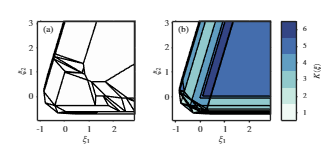

%% ----- figure style -----
fig_w = plot_cfg.fig_w;
fig_h = plot_cfg.fig_h;

fs_axis = plot_cfg.fs_axis;
fs_label = plot_cfg.fs_label;
fs_panel = plot_cfg.fs_panel;

fillXi = [0.96 0.96 0.96];

edgeColor_a = [0.42 0.42 0.42];   % PWA inner lines
edgeColor_b = [0.35 0.35 0.35];   % active-region inner lines
outerColor = [0.00 0.00 0.00];
axisColor = [0.15 0.15 0.15];

lw_region_a = 0.28;
lw_region_b = 0.24;
lw_outer = 0.85;

nK = kappa_max - kappa_min + 1;
cmap_base = [
    0.94 0.98 0.96
    0.78 0.91 0.88
    0.57 0.79 0.80
    0.38 0.62 0.76
    0.27 0.43 0.68
    0.20 0.27 0.52
];
cmapK = interp1(linspace(0, 1, size(cmap_base, 1)), cmap_base, linspace(0, 1, nK));

fig = figure('Color', 'w', 'Units', 'inches', 'Position', [1.0, 1.0, fig_w, fig_h]);
set(fig, 'Renderer', 'painters');

tl = tiledlayout(fig, 1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

%% ----- panel (a): explicit mpQP partition -----
ax1 = nexttile(tl, 1);
hold(ax1, 'on');
box(ax1, 'on');

plot(Xi_clip, 'color', fillXi, 'alpha', 0.18);

for k = 1:nCRclip
    plot(CRclip{k}, 'wire', true, 'color', edgeColor_a, 'LineWidth', lw_region_a);
end

plot(Xi_clip, 'wire', true, 'color', outerColor, 'LineWidth', lw_outer);

axis(ax1, 'equal');
xlim(ax1, view_box(1, :));
ylim(ax1, view_box(2, :));

set(ax1, 'FontSize', fs_axis, 'LineWidth', 0.55, ...
    'TickLabelInterpreter', 'latex', 'TickDir', 'out', ...
    'XGrid', 'off', 'YGrid', 'off', 'Layer', 'top', ...
    'XColor', axisColor, 'YColor', axisColor);

xlabel(ax1, '$\xi_1$', 'Interpreter', 'latex', 'FontSize', fs_label);
ylabel(ax1, '$\xi_2$', 'Interpreter', 'latex', 'FontSize', fs_label);

text(ax1, 0.04, 0.96, '(a)', 'Units', 'normalized', ...
    'Interpreter', 'latex', 'FontSize', fs_panel, ...
    'VerticalAlignment', 'top', 'BackgroundColor', 'w', 'Margin', 0.5);

%% ----- panel (b): Cert active validity-region cover -----
ax2 = nexttile(tl, 2);
hold(ax2, 'on');
box(ax2, 'on');

levels = (kappa_min - 0.5):1:(kappa_max + 0.5);
contourf(ax2, xg1, xg2, Kappa, levels, 'LineStyle', 'none');

colormap(ax2, cmapK);
clim(ax2, [kappa_min - 0.5, kappa_max + 0.5]);

for k = 1:nActPlot
    plot(Act{k}, 'wire', true, 'color', edgeColor_b, 'LineWidth', lw_region_b);
end

plot(Xi_clip, 'wire', true, 'color', outerColor, 'LineWidth', lw_outer);

axis(ax2, 'equal');
xlim(ax2, view_box(1, :));
ylim(ax2, view_box(2, :));

set(ax2, 'FontSize', fs_axis, 'LineWidth', 0.55, ...
    'TickLabelInterpreter', 'latex', 'TickDir', 'out', ...
    'XGrid', 'off', 'YGrid', 'off', 'Layer', 'top', ...
    'XColor', axisColor, 'YColor', axisColor);

xlabel(ax2, '$\xi_1$', 'Interpreter', 'latex', 'FontSize', fs_label);
ylabel(ax2, '$\xi_2$', 'Interpreter', 'latex', 'FontSize', fs_label);

text(ax2, 0.04, 0.96, '(b)', 'Units', 'normalized', ...
    'Interpreter', 'latex', 'FontSize', fs_panel, ...
    'VerticalAlignment', 'top', 'BackgroundColor', 'w', 'Margin', 0.5);

cb = colorbar(ax2, 'Location', 'eastoutside');
cb.Ticks = kappa_min:kappa_max;
cb.TickLabelInterpreter = 'latex';
cb.FontSize = 5.6;
cb.LineWidth = 0.45;
cb.TickDirection = 'out';
cb.Label.String = '$K(\xi)$';
cb.Label.Interpreter = 'latex';
cb.Label.FontSize = 6.0;

%% ===================== Export figure =====================
pdf_name = plot_cfg.pdf_name;
exportgraphics(fig, pdf_name, 'ContentType', 'vector');


fprintf(['\n==================== REGION PLOT INFO ====================\n' ...
         'nCR=%d, nCRclip=%d, nActLaw=%d, nActPlot=%d, nFullLaw=%d, kappa=[%d,%d]\n' ...
         'saved: %s\n' ...
         '==========================================================\n'], ...
         nCR, nCRclip, nAct, nActPlot, numel(OPCert.law), kappa_min, kappa_max, pdf_name);


==================== REGION PLOT INFO ====================
nCR=52, nCRclip=38, nActLaw=23, nActPlot=23, nFullLaw=71, kappa=[1,6]
saved: sim_region_compare.pdf
